assert(endsWith(pwd, "\defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Reconstruction matrix

load('precompute_30x30.mat')

x = elems_center(1,:);
y = elems_center(2,:);

n = size(S,2);
lambda = 1e-14;
S_ct = pagectranspose(S);
R = pagemldivide(pagemtimes(S_ct,S) + lambda*speye(n), S_ct);

clear n lambda S_ct

#### Perform reconstruction

B_m = readmatrix("Forward_data/DCS_B_hole.csv", 'CommentStyle','%');
B_m = permute(B_m, [1 3 2]);

delta_B = B_m - B_bar;

delta_p = pagemtimes(R, delta_B);

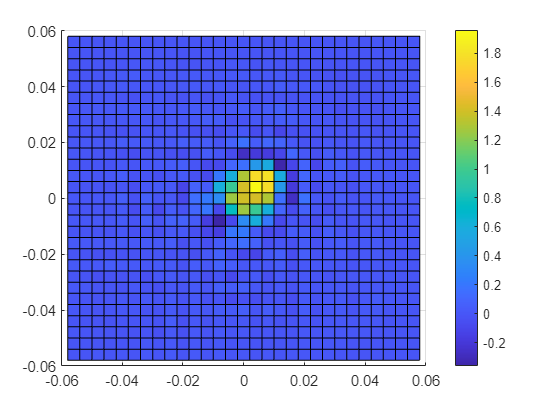

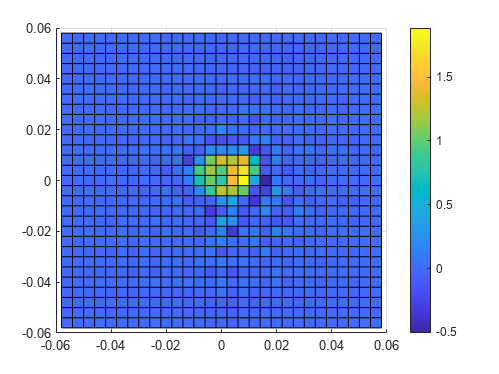

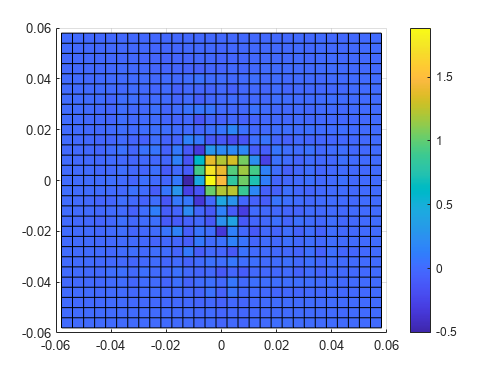

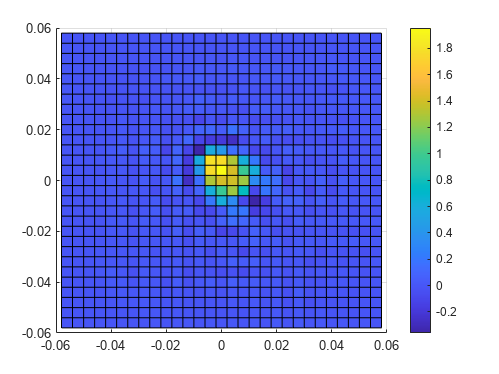

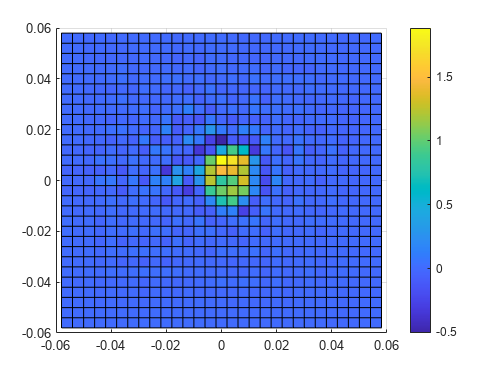

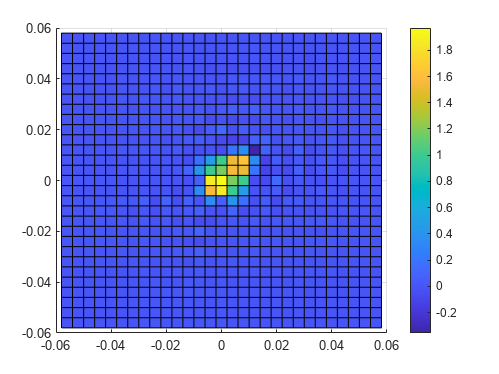

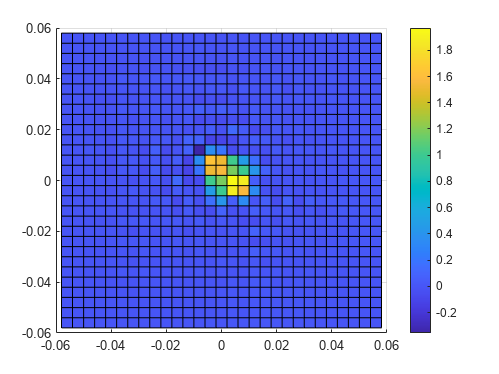

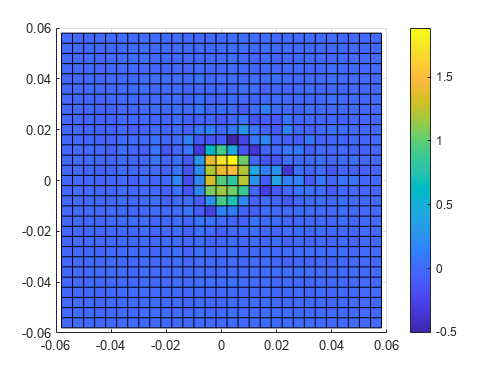

for coil_num = 1:size(S,3)
p = delta_p(:,:,coil_num).';
p = real(p);

x = reshape(x, 30, []);
y = reshape(y, 30, []);
p = reshape(p, 30, []);

figure
surf(x, y, p);
colorbar
view(2)
end